# Run Your Function

Calling `getElevations Correctly`

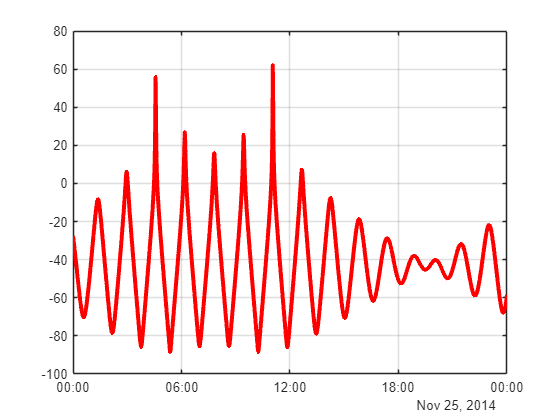

tstart = datetime([2014 11 25]);
tspan = days(1);
dt = minutes(1);
t = (tstart:dt:(tstart + tspan))';
file = "./data/iss.txt";
obs = [42 -71 0];

elv = getElevations(file, t, obs, "Color", "r", "LineWidth", 3);

**Calling **`getElevations`** with Invalid Line Property**

This currently errors, but you will fix it in this activity.

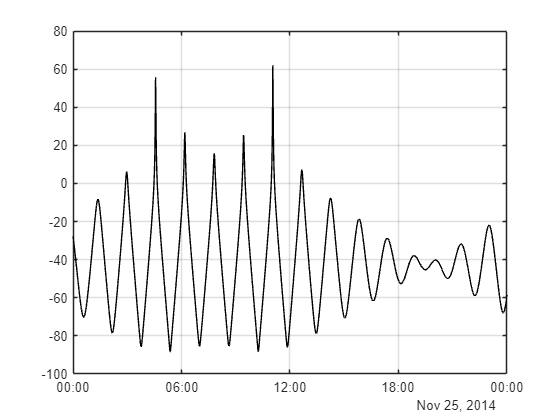

elv = getElevations(file, t, obs, "Color", "r", "Width", 3);

# Calculates the elevation (angle from the horizon) of a satellite

ELV = GETELEVATIONS(FILE,T,OBS) calculates the elevation angles ELV for the satellite defined by the orbital parameters in the text file FILE for the times in the datetime vector T, as seen by an observer at the location defined by the vector OBS.

The `getElevations` function not only calculates a satellite's elevations, but it also creates a plot. Here, the user can provide additional inputs to customize the plot using standard plot options, which are then passed to the `plot` function on line 14.

What happens if the user provides an invalid plot option? Ideally, `getElevations` would not stop because of an invalid plot option; it would display a warning to the user about the invalid plot option, and return the calculated elevations.

function [elv,t] = getElevations(file,t,obs,varargin)
    % Read orbital parameters from file
    p = readparameters(file);
    
    % Calculate elevations
    elv = satellitefix(p,t,obs);
    
    % TODO: Run the following command in a try block.
    % Catch the error and display the 'message' from the
    % exception object using the function 'warning'.
    
    try
        plot(t,elv,varargin{:})
    catch MExp
        warning(MExp.message)
        plot(t,elv,"k")
    end
    grid on
end

# Creates a structure of orbital parameters read from file

P = READPARAMETERS(FILE) reads the two-line element set (TLE) file FILE (string) and returns a structure P containing the epoch [datetime], inclination [degrees], RA of the ascending node [degrees], eccentricity [number], argument of perigee [degrees], mean anomaly [degrees], and mean motion [revolutions/day]. All angles are given as scalar numbers.

function p = readparameters(fname)
    % Get raw text from file; split into two lines
    txt = strsplit(fileread(fname),'\n');
    
    % Extract epoch year
    ey = str2double(txt{1}(19:20));
    % Convert 2-digit epoch year to 4-digit year
    % (00-60 -> 2000-2060, 61-99 -> 1961-1999)
    ey = 1900 + ey + 100*(ey < 60);
    % Extract epoch day
    ed = str2double(txt{1}(21:32));
    
    % Build output structure
    p.epoch = datetime(ey,1,1) + days(ed - 1);
    
    p.inclination = str2double(txt{2}(9:16));
    p.RAAN = str2double(txt{2}(18:25));
    p.eccentricity = str2double(['0.',txt{2}(27:33)]);
    p.argPerigee = str2double(txt{2}(35:42));
    p.anomaly = str2double(txt{2}(44:51));
    p.motion = str2double(txt{2}(53:63));
end

# Determine local azimuth and elevation of a satellite at given times

[EL,AZ] = SATELLITEFIX(T,PARAMS,OBS) calculates the elevation (EL), in degrees from horizontal, and azimuth (AZ), in degrees from North, of a satellite defined by the orbital parameters in the structure PARAMS for each time in the datetime array T, as observed from a position specified in the 3-element vector OBS, representing the observer's latitude [deg], longitude [deg], and altitude [km].

[EL,AZ,LAT,LON,R] = SATELLITEFIX(...) also returns the location of the satellite in terms of latitude (LAT), longitude (LON), in Earth-centered fixed coordinates, and radius R (in km from the center of the Earth).

function [el,az,satlat,satlon,r] = satellitefix(p,t,obsloc)
    % Extract the location components
    lat = obsloc(1);
    lon = obsloc(2);
    alt = obsloc(3);
    
    % cos(phi) and sin(phi) -- used a few times
    cp = cosd(lat);
    sp = sind(lat);
    
    % Get satellite position in Earth coordinates (lat/lon/r)
    [satlat,satlon,r] = satelliteposition(t,p);
    % Convert to Cartesian
    xsat = r.*cosd(satlon).*cosd(satlat);
    ysat = r.*sind(satlon).*cosd(satlat);
    zsat = r.*sind(satlat);
    
    % Observer's radial distance
    robs = 1/sqrt((cp/6378.135)^2 + (sp/6356.752)^2) + alt;
    % Convert to Cartesian coordinates
    xobs = robs*cosd(lon)*cosd(lat);
    yobs = robs*sind(lon)*cosd(lat);
    zobs = robs*sind(lat);
    
    % Difference between satellite location and observer
    dx = xsat - xobs;
    dy = ysat - yobs;
    dz = zsat - zobs;
    
    % Convert to local (Cartesian) coordinates
    st = sind(lon);
    ct = cosd(lon);
    xt = sp*ct*dx + sp*st*dy - cp*dz;
    yt = ct*dy - st*dx;
    zt = cp*ct*dx + cp*st*dy + sp*dz;
    
    % Convert to az/el
    az = mod(180*atan2(yt,-xt)/pi,360);
    zt = zt./sqrt(xt.*xt+yt.*yt+zt.*zt);  % normalize (unit vector)
    el = asind(zt);
end

# Determine (ECF) position of a satellite at a given time

[LAT,LON] = SATELLITEPOSITION(T,PARAMS) calculates the latitude (LAT) and longitude (LON), in Earth-centered fixed coordinates, of a satellite defined by the orbital parameters in the structure PARAMS for each time in the datetime array T.

[LAT,LON,RADIUS] = SATELLITEPOSITION(...) also returns the satellite's distance, in km, from the center of the Earth.

function [lat,lon,r] = satelliteposition(t,satparams)
% Extract parameters
inc = satparams.inclination;  % Inclination [deg]
e = satparams.eccentricity;   % Eccentricity []
n = satparams.motion;         % Mean Motion [rev/day]

% Semi-major axis
a = (2.975541313977700e+015/(2*pi*n)^2)^(1/3); % Constant is G*M_Earth

% Constant for converting between degrees and radians
rd = 180/pi;

% Calculate time since epoch
dt = days(t - satparams.epoch);
% Number of rotations since epoch time
ndt = n*dt;
% Current mean anomaly (Mt0 + fractional part of ndt)
M = mod(satparams.anomaly + 360*(ndt - floor(ndt)),360)/rd;
% Solve Kepler's equation to get eccentric anomaly
E = M;
f = e*sin(E) + M;
while norm(E-f) > 1e-6
    E = f;
    f = e*sin(E) + M;
end
% Calculate true anomaly
nu = 2*rd*atan2(sqrt((1+e)/(1-e))*sin(E/2),cos(E/2));

% Account for precession of orbit (RAAN and Arg of Perigee)
[aWt,wt] = precession(a,e,inc,ndt,satparams.RAAN,satparams.argPerigee);
% Argument of Latitude
mu = mod(wt + nu,360);
% Difference in RA between satellite's geocentric position and RAAN
Da = acosd(cosd(mu) ./ sqrt(1-sind(inc)^2*sind(mu).^2));
idx = ((inc < 90) & (mu > 180)) | ((90 < inc) & (180 > mu));
Da(idx) = 360 - Da(idx);

% Geocentric coordinates (RA and DEC)
ag = mod(aWt + Da,360);
dg = sign(sind(mu)).*acosd(cosd(mu)./cosd(Da));

% Radial distance
r = a*(1-e^2)./(1+e*cosd(nu));

lat = dg;
% Get longitude by shifting by Greenwich ST (then wrap to [-180 180])
lon = mod(ag - 15*siderealtime(t,0) + 180,360) - 180;
end

# Determine effects of precession on satellite location

[AWT,WT] = PRECESSION(A,E,I,NDT,AW,W) calculates the right ascension of the ascending node and the argument of perigee for the satellite due to precession. A is the semi-major axis, E is the eccentricity, I is the inclination, NDT is the number of rotations since epoch, aW is the original value for the right ascension of the ascending node and w is the original argument of perigee.

## Example

`[aWt,wt] = precession(6768,0.0022,51.6389,-170.28,187.86,10.63);`

function [aWt,wt] = precession(a,e,inc,ndt,aW,w)
    aE = 1;
    a1 = a/6378.135;
    J2 = 1.082616e-3;
    d1 = (3*J2*aE^2*(3*cosd(inc)^2 - 1))/(4*a1^2*(1-e^2)^(3/2));
    a0 = -a1*(134*d1^3/81 + d1^2 + d1/3 - 1);
    p0 = a0*(1-e^2);
    aWt = aW + 360*(-3*J2*aE^2*ndt*cosd(inc) / (2*p0^2));
    wt = w + 360*(3*J2*aE^2*ndt*(5*cosd(inc)^2 - 1)/(4*p0^2));
end

# Determine local sidereal time

LST = SIDEREALTIME(T,LON) calculates the sidereal time given the (UTC) time T [datetime] and the longitudinal position LON [in degrees].

function LST = siderealtime(t,lon)
    % J2000 (shifted Julian date)
    D = days(t - datetime(2000,1,1,12,0,0));
    % Greenwich mean sidereal time
    GMST = mod(18.697374558 + 24.06570982441908*D,24);
    % Adjust for local longitude
    LST = mod(GMST + 1.0027379*lon/15,24);
end